modulePath = 'C:/Users/Asus/Studia/Projekt IPS/dane - semestr 5/MATLAB_project/python_modules';
insert(py.sys.path, int32(0), modulePath);
load("C:\Users\Asus\Studia\Projekt IPS\dane - semestr 5\MATLAB_project\ab_diff_zestaw.mat")

function pred_vector = model_chronos_expanding(y_train, y_test, step_length)
    modul = py.importlib.import_module('chronos_module_window');
    
    py.importlib.reload(modul);

    y_train_list = py.list(y_train(:)'); 
    y_test_list  = py.list(y_test(:)');
    
    result_list = modul.run_forecast_expanding(y_train_list, y_test_list, int32(step_length));
    
    pred_vector = result_list.double;
end
% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);

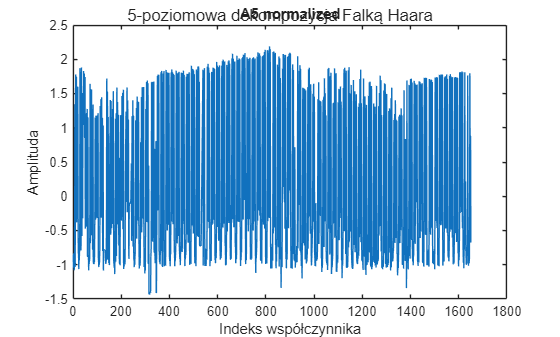

% ZBIÓR TRENINGOWY
[c, l] = wavedec(ab_diff_train_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji A i szczegółów D
A1 = appcoef(c, l, 'haar', 1);
A5 = appcoef(c, l, 'haar', 5);

D5 = detcoef(c, l, 5);
D4 = detcoef(c, l, 4);
D3 = detcoef(c, l, 3);
D2 = detcoef(c, l, 2);
D1 = detcoef(c, l, 1);

% normalizacja współczynników
[D2_norm, center_D2, scale_D2] = normalize(D2);
[A5_norm, center_A5, scale_A5] = normalize(A5);

% 2. RYSOWANIE WYKRESÓW
plot(A5_norm);
title('A5 normalized');
xlabel('Indeks współczynnika');
ylabel('Amplituda');
sgtitle('5-poziomowa dekompozycja Falką Haara');


% TEST
[c_test, l_test] = wavedec(ab_diff_test_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji (Trend) z poziomu 5
A1_test = appcoef(c_test, l_test, 'haar', 1);
A5_test = appcoef(c_test, l_test, 'haar', 5);

D5_test = detcoef(c_test, l_test, 5);
D4_test = detcoef(c_test, l_test, 4);
D3_test = detcoef(c_test, l_test, 3);
D2_test = detcoef(c_test, l_test, 2);
D1_test = detcoef(c_test, l_test, 1);

% Normalizacja współczynników testowych
D2_test_norm = (D2_test - center_D2) ./ scale_D2;
A5_test_norm = (A5_test - center_A5) ./ scale_A5;

dlugosc_testu_oryginalna = 2880; % Horyzont w oryginalnej dziedzinie czasu (2880 próbek)

step_length = 1;
dlugosc_testu_A5 = ceil(dlugosc_testu_oryginalna / 32);
dlugosc_testu_D2 = ceil(dlugosc_testu_oryginalna / 4);

% Przewidywania A5 - model CHRONOS
A5_pred_norm = model_chronos_expanding(A5_norm, A5_test_norm(1:dlugosc_testu_A5), step_length)

CUDA dostepne: True
Wersja: 2.9.1+cu126
Ładowanie modelu Chronos-2 (Singleton)...
[Python Chronos] Start Expanding Window. Kroki: 90, Step: 1
[Python Chronos] Krok 1/90
[Python Chronos] Krok 2/90
[Python Chronos] Krok 3/90
[Python Chronos] Krok 4/90
[Python Chronos] Krok 5/90
[Python Chronos] Krok 6/90
[Python Chronos] Krok 7/90
[Python Chronos] Krok 8/90
[Python Chronos] Krok 9/90
[Python Chronos] Krok 10/90
[Python Chronos] Krok 11/90
[Python Chronos] Krok 12/90
[Python Chronos] Krok 13/90
[Python Chronos] Krok 14/90
[Python Chronos] Krok 15/90
[Python Chronos] Krok 16/90
[Python Chronos] Krok 17/90
[Python Chronos] Krok 18/90
[Python Chronos] Krok 19/90
[Python Chronos] Krok 20/90
[Python Chronos] Krok 21/90
[Python Chronos] Krok 22/90
[Python Chronos] Krok 23/90
[Python Chronos] Krok 24/90
[Python Chronos] Krok 25/90
[Python Chronos] Krok 26/90
[Python Chronos] Krok 27/90
[Python Chronos] Krok 28/90
[Python Chronos] Krok 29/90
[Python Chronos] Krok 30/90
[Python Chronos] Krok 31/90

A5_pred_norm =    -0.4648    1.5547   -0.7891   -0.8438    1.6016    0.2402   -0.3516    1.7188    0.0913   -0.9023   -0.9062   -0.8633   -0.9375   -0.8711   -0.8555   -0.5234    1.5078   -0.6758   -0.5078    1.4844   -0.3047   -0.3301    1.5938   -0.0388   -0.4023    1.5859   -0.2363   -0.4707    1.7969    0.0903   -0.9102   -0.8945   -0.9375   -0.9062   -0.8828   -0.9141   -0.4434    1.7344   -0.1562   -0.3574    1.7812   -0.1533   -0.2139    1.7344    0.1357   -0.4258    1.8516    0.4902   -0.4023    1.8203


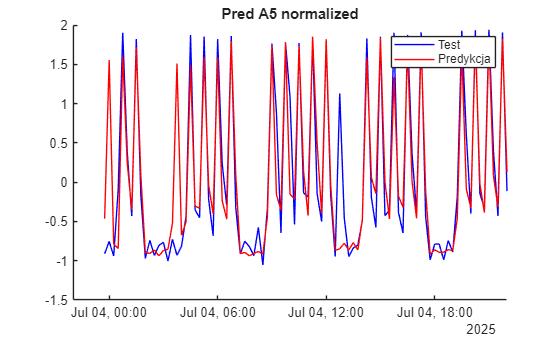


% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:dlugosc_testu_A5), A5_test_norm(1:dlugosc_testu_A5), 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:dlugosc_testu_A5), A5_pred_norm, 'Color','red','DisplayName','Predykcja');
title('Pred A5 normalized');
legend;

% Przewidywania D2 - model CHRONOS
D2_pred_norm = model_chronos_expanding(D2_norm, D2_test_norm(1:dlugosc_testu_D2), step_length)

CUDA dostepne: True
Wersja: 2.9.1+cu126
Ładowanie modelu Chronos-2 (Singleton)...
[Python Chronos] Start Expanding Window. Kroki: 720, Step: 1
[Python Chronos] Krok 1/720
[Python Chronos] Krok 2/720
[Python Chronos] Krok 3/720
[Python Chronos] Krok 4/720
[Python Chronos] Krok 5/720
[Python Chronos] Krok 6/720
[Python Chronos] Krok 7/720
[Python Chronos] Krok 8/720
[Python Chronos] Krok 9/720
[Python Chronos] Krok 10/720
[Python Chronos] Krok 11/720
[Python Chronos] Krok 12/720
[Python Chronos] Krok 13/720
[Python Chronos] Krok 14/720
[Python Chronos] Krok 15/720
[Python Chronos] Krok 16/720
[Python Chronos] Krok 17/720
[Python Chronos] Krok 18/720
[Python Chronos] Krok 19/720
[Python Chronos] Krok 20/720
[Python Chronos] Krok 21/720
[Python Chronos] Krok 22/720
[Python Chronos] Krok 23/720
[Python Chronos] Krok 24/720
[Python Chronos] Krok 25/720
[Python Chronos] Krok 26/720
[Python Chronos] Krok 27/720
[Python Chronos] Krok 28/720
[Python Chronos] Krok 29/720
[Python Chronos] Krok 30/

D2_pred_norm =     0.0094    0.0011   -0.0054   -0.0142   -0.0388   -0.0452   -0.0513   -0.0093   -0.0040    0.0226    0.0231    0.0303    0.0344    0.0383    0.0334    0.0457    0.0304    0.0437    0.0287    0.0226    0.0232    0.0103    0.0006    0.0060    0.0156    0.0022    0.0130   -0.0231   -0.0415   -0.0500   -0.0596   -0.0099   -0.0096    0.0221    0.0240    0.0228    0.0270    0.0337    0.0317    0.0403    0.0278    0.0322    0.0366    0.0266    0.0250    0.0033    0.0033    0.0164    0.0104    0.0057


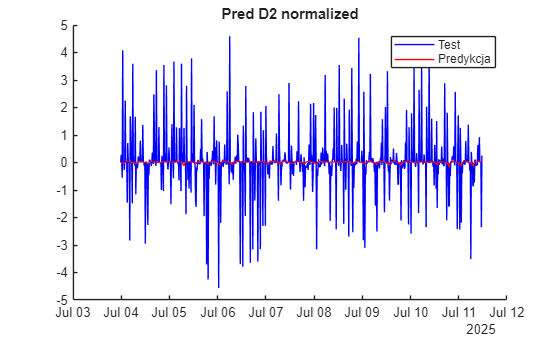


% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:dlugosc_testu_D2), D2_test_norm(1:dlugosc_testu_D2), 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:dlugosc_testu_D2), D2_pred_norm, 'Color','red','DisplayName','Predykcja');
title('Pred D2 normalized');
legend;

% DENORMALIZACJA
% Odwracamy proces: x = y * scale + center
A5_pred = (A5_pred_norm .* scale_A5) + center_A5;
D2_pred = (D2_pred_norm .* scale_D2) + center_D2;

% Obliczamy długości wektorów dla brakujących poziomów (dla zadanego horyzontu)
len_A5 = length(A5_pred);
len_D5 = len_A5;      % Z własności Haara
len_D4 = len_A5 * 2;
len_D3 = len_A5 * 4;
len_D2 = len_A5 * 8;
len_D1 = len_A5 * 16;

% Budowa wektora c_pred
c_pred = [
    A5_pred';             % Predykcja CHRONOS
    zeros(len_D5, 1);     % D5 - zerujemy
    zeros(len_D4, 1);     % D4 - zerujemy
    zeros(len_D3, 1);     % D3 - zerujemy
    D2_pred';             % Predykcja CHRONOS
    zeros(len_D1, 1);     % D1 - zerujemy
];

total_len = length(c_pred);
l_pred = [
    length(A5_pred);
    length(A5_pred);      % D5
    length(A5_pred)*2;    % D4
    length(A5_pred)*4;    % D3
    length(A5_pred)*8;    % D2
    length(A5_pred)*16;   % D1
    length(A5_pred)*32    % Całkowita długość sygnału
];

final_prediction = waverec(c_pred, l_pred, 'haar');      % podejście: A5 i D2 CHRONOS
y_test = ab_diff_test_norm(1:length(final_prediction))';

mae_score = mae(y_test, final_prediction')

mae_score = 0.1934

mape_score = mape(y_test, final_prediction')

mape_score = 66.8683

rmse_score = rmse(y_test, final_prediction')

rmse_score = 0.2525

r2_classic = R2_classic(y_test, final_prediction')

r2_classic = 0.4680

r2_alt = R2_alt(y_test, final_prediction')

r2_alt = 0.5377

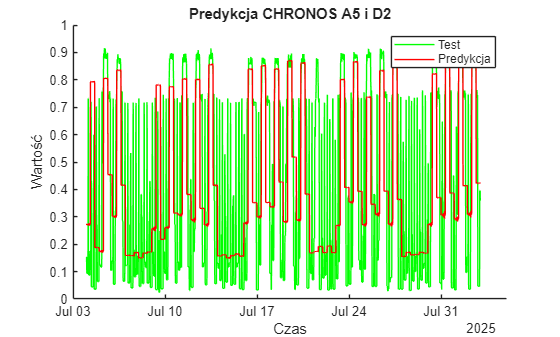


figure;
hold on;
plot(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ab_diff_test_norm(1:dlugosc_testu_oryginalna), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:dlugosc_testu_oryginalna), final_prediction, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja CHRONOS A5 i D2")
legend;

% Tworzenie tabeli z czasem, danymi i predykcją
T_z_czasem = table(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ...
                   ab_diff_test_norm(1:dlugosc_testu_oryginalna), ...
                   final_prediction(1:dlugosc_testu_oryginalna), ...
    'VariableNames', {'Czas', 'Dane_Prawdziwe', 'Predykcja'});

writetable(T_z_czasem, "pred_ab_A5_D2_CHRONOS_month_"+ num2str(step_length)+".xlsx");